# **Mimic Joint Resolution**

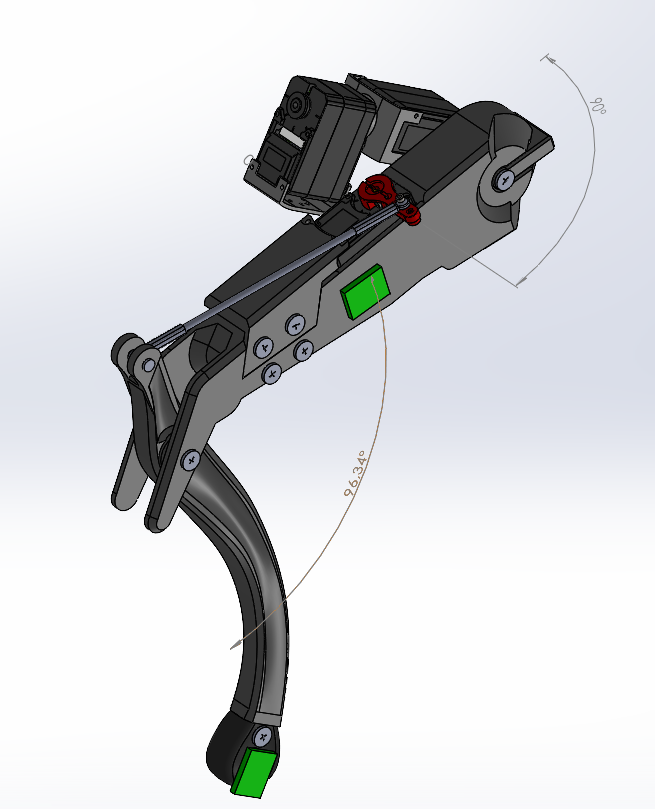

% Data
% Data
ArTh = [90; 0; 45; 90; 135; 180];
ShTh = [96.31; 117.76; 111.74; 96.32; 78.92; 70.63];

% Convert to radians
ArTh_rad = deg2rad(ArTh);
ShTh_rad = deg2rad(ShTh);

% Standard linear regression (y = ax + b)
coeffs = polyfit(ArTh_rad, ShTh_rad, 1);
ShTh_pred = coeffs(1) * ArTh_rad + coeffs(2);

% Print equation
fprintf('Linear regression: ShTh = %.4f * ArTh + %.4f\n', coeffs(1), coeffs(2))

Linear regression: ShTh = -0.2824 * ArTh + 2.1065


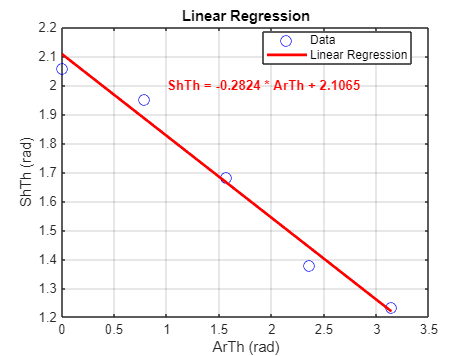


% Plot
figure
plot(ArTh_rad, ShTh_rad, 'bo', 'MarkerSize', 8, 'DisplayName', 'Data')
hold on
plot(ArTh_rad, ShTh_pred, 'r-', 'LineWidth', 2, 'DisplayName', 'Linear Regression')
xlabel('ArTh (rad)')
ylabel('ShTh (rad)')
title('Linear Regression')
grid on
legend('Location', 'best')

% Add equation to plot
text(1, 2, sprintf('ShTh = %.4f * ArTh + %.4f', coeffs(1), coeffs(2)), ...
   'Color', 'red', 'FontWeight', 'bold', 'FontSize', 10)